# Running Python Code With MATLAB

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

There are many programming languages in the world and they all have different features. You may have occasions where you want to reuse existing code, call on functionality from another language, or collaborate with someone who prefers to work in a different language than you. It is quite possible to use multiple programming languages together, although in some cases the interface may be awkward if the underlying structures are different. This script introduces a Live Task that can be used as a graphical user interface to run Python code from MATLAB.

This script is intended to be run one section at a time, in order. If you choose to skip around, you may encounter errors.

## Getting ready

### Step 1: Check your MATLAB version 

Including user-authored Live Tasks is only supported starting in R2022a. What version are you running?

releaseInfo = matlabRelease;
str = "This is release " + releaseInfo.Release + ",";
if isMATLABReleaseOlderThan("R2022a")
    disp(str + " so it will not run this example.")
else
    disp(str + " so you can proceed with this script.")
end

This is release R2023b, so you can proceed with this script.


### Step 2: Check your Python version

You must have Python installed, and it must be a [supported version of Python](https://www.mathworks.com/support/requirements/python-compatibility.html) for your MATLAB version. For R2022a, you need to use 2.7, 3.8, or 3.9. What version are you using?

CheckPythonVersion

You are running Python 3.10
Python was already on your MATLAB path.
You are running compatible versions of MATLAB and Python.


If you do not have a supported version of Python installed, follow the instructions in the [documentation to install and select](https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html) a supported version. If you have a supported version of Python installed, but it is not on your MATLAB path, you will need to add it using `addpath`

### Step 3: Download and install the MATLAB Live Task for Python

Clone the GitHub repository containing [MATLAB-Live-Task-for-Python](https://github.com/mathworks/MATLAB-Live-Task-for-Python.git). 

if isMATLABReleaseOlderThan("R2023b")
    disp("Follow the alternate instructions below.")
else
    gitclone("https://github.com/mathworks/MATLAB-Live-Task-for-Python.git");
    % Change directories to access the install script without adding it to
    % your MATLAB path
    cd MATLAB-Live-Task-for-Python
    install
    cd ..
end

#### Alternate Instructions

You can find the **Home** tab of the toolstrip and select **New**. 

  **Pro-tip**.If you have undocked your script, you will need to return to the main MATLAB window to find **Home**.

In that drop-down menu, select **Project** and then **From Git**. Type or paste the address  [`https://github.com/mathworks/MATLAB-Live-Task-for-Python.git`](https://github.com/mathworks/MATLAB-Live-Task-for-Python.git) into the **Repository Path** field:

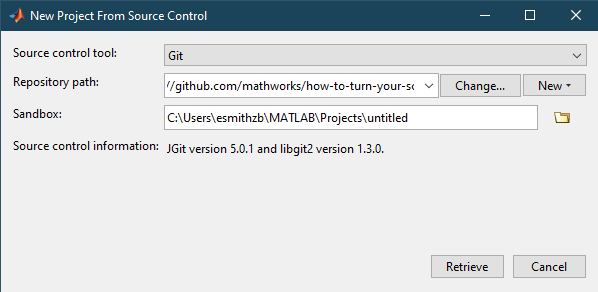

You should the Sandbox location. A good choice would be your current location with a more descriptive name such as MATLAB-Live-Task-for-Python. You can copy and paste the location created as `GoodSandboxLocation` into the Sandbox field:

CurrentLocation = pwd;
GoodSandboxLocation = string(CurrentLocation) + filesep + "MATLAB-Live-Task-for-Python";
disp(GoodSandboxLocation)

Then select **Retrieve**. If the folder identified as the Sandbox does not exist, you will be prompted to create it.  

Because there is no project in the MATLAB-Live-Task-for-Python repository, you will be prompted to create one. In this dialog, select "Cancel" because you do not need a project, you just want to be able to install the Live Task. 

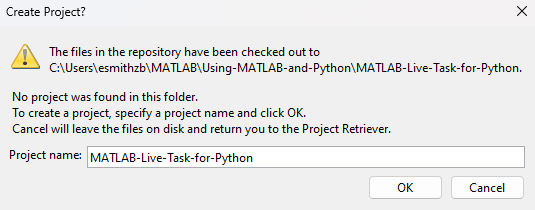

  **Pro-tip**. If you downloaded the MATLAB-Live-Task-for-Python into the Programming-A-Starter-Project-Using-MATLAB-with-Python directory, you can programmatically change directories and install the new Live Task by uncommenting and running the code below. 

% cd MATLAB-Live-Task-for-Python
% install
% cd ..

If you did not download the repository into your current folder, change directories into the MATLAB-Live-Task-for-Python folder that you just cloned and then run the installation script 

which will open a pop-up window 

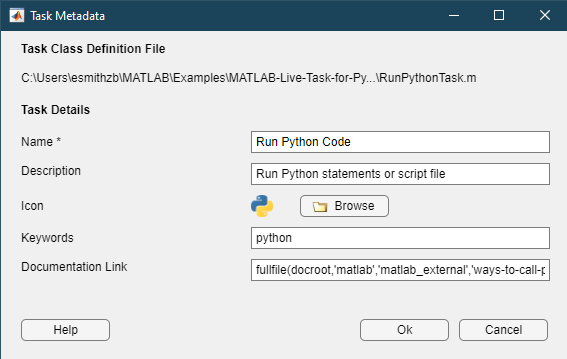

where you could access or change the name, description, icon, keywords, or documentation link for this Live Task. In this case, all the default values are fine. Select **Ok** to finish the installation. Since this process is installing code you downloaded from the internet your operating system may also prompt you to allow the install. 

Change directories back to Programming-A-Starter-Project-Using-MATLAB-with-Python:

proj = currentProject;
cd(proj.RootFolder)

## Identify Code to Run

Here is a few lines of Python code to compute tax due.

You cannot copy this to a command line and run it, but the Run Python Code live script will build the necessary wrapping code, although you may need to specify what values are being passed in from MATLAB variables.

## Investigate the Run Python Code Live Task

Insert the Live Task by going to the **Live Editor** tab, selecting the **Task** drop-down in the **Code **section of the toolstrip, and then selecting **Run Python Code**.

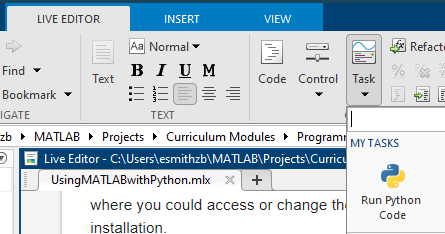

  **Pro-tip**. If you are using MATLAB Online, you may need to reload the page to refresh the drop-down menu.

Alternatively, you may simply type `python` in a code block, and the autocomplete feature will suggest the appropriate task:

Type some code in the box such as 

and run the section. Simply clicking outside of the text entry box will run the code while the "Autorun" option is selected.

Once code has been generated, you can select the "expand" arrow 

  on the bottom of the Live Task, or the breadcrumbs in the top right of the Live Task where you can select "Controls and Code", 

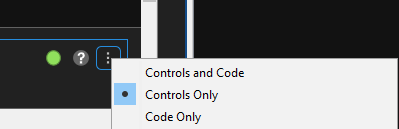

or even "Code Only" once you are satisfied with the code.  

 **Warning**

The first time you run this Live Task, it will add variables to your Python workspace. For future iterations, it will rename the variables including the output variables. This is a good reason to determine what code you would like to run and then switch to just using the code and not the Live Task.  

## Try Running Python Code

### Run Python statements

  **Try**. Test your ability to use the Run Python Code Live Task.

- Clear your workspace, for ease of navigation, and set up variables to use as input.

clear
dollars = "$35.12";
percent = "5.9%";

        2. Insert the Live Task below by going to the **Live Editor** tab, selecting the **Task** drop-down in the **Code **section of the toolstrip, and then selecting **Run Python Code**.

  **Pro-tip**. If you are using MATLAB Online, you may need to reload the page to refresh the dropdown menu.

Alternatively, you may simply type `python` in a code block, and the autocomplete feature will suggest the appropriate task:

        3. Select the `+` to add Input and Output variables. You should have two input variables, the MATLAB variables `dollars` and `percent`, which become the Python variables `dollars` and `percent` and one output variable, `tax`. 

        4. Copy the sample Python code into the Live Task and run it with different input values. 

If you want to use more elegant output formating, that is available depending on your Python version:

        5. Check that `tax` is a variable in the MATLAB Workspace. What value does it contain? 

### Run Python scripts

If you have a Python script, the Run Python Code Live Task also supports running scripts. To test this capability, there is a Python script in the `FunctionLibrary` folder called `helloworld.py` that takes one input variable called `name`. First, define a value for `name`:

name = "Team";

  **Try. Use the Run Python Code Live Task to run **`helloworld.py`**.**

        1. In the code box, below, insert the Run Python Code Live Task. 

        2. Select "Python script file" in the Run Python Code Live Task.

        3. Add the input variable `name` from the Workspace with Python variable name `name`.

        4. Use your file selector to select the `helloworld.py` file in the `FunctionLibrary` folder.

Hint: If you have trouble locating `helloworld.py` you can use the command

        5. Run this section. 

## Creating a Simple Weather Display

Now that you have installed and tested the Run Python Code Live Task, let's use it to help build a script that will check the current weather and short-term forecast and display the results. 

edit CheckingTheWeather.mlx

## Further Explorations

If this has whet your appetite, it is possible to go much farther with integrating code back and forth between [MATLAB and Python](https://www.mathworks.com/campaigns/offers/matlab-python-cheat-sheets.html). 

- Documentation on [calling Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html)

- Documentation on [calling MATLAB from Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html)

- A deep learning example for [speech recognition](https://github.com/matlab-deep-learning/coexecution_speech_command)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))